clear all;


% doped Si channel widths
w = [75 150 225 300]; % um

% measured resistances from package
Rt = [1168 579 408 311.5]; % Ohm

% find intercept 
% R = (rho*L) / (w*d), so we extrapolate linear relationship with R = k/w:
Rt0 = interp1(1./w, Rt, 0, 'linear', 'extrap')

Rt0 = 22.0000


% get best fit line
Rt_coefs = polyfit(1./w, Rt, 1);
w_line = 0:10:10000;
Rt_line = Rt_coefs(1) * 1./w_line + Rt_coefs(2);
Rt_line(end)

ans = 30.2088

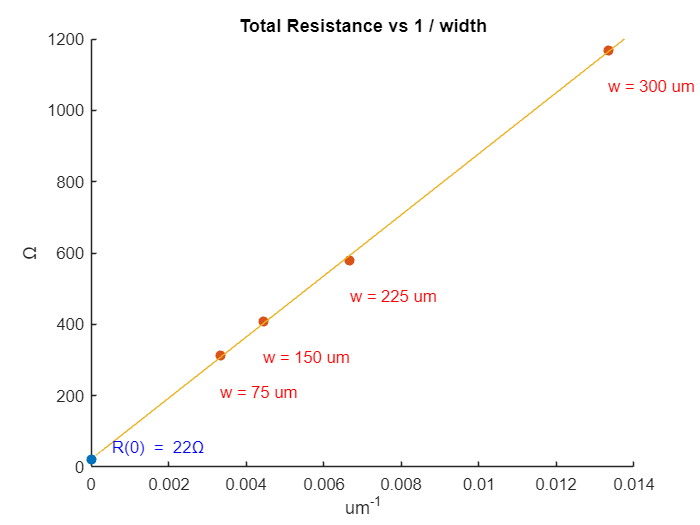


% plot total resistance
figure
scatter(0, Rt0, "filled", "Color", 'red')
hold on
scatter(1./w, Rt, "filled", "Color", 'blue')
hold on
plot(1./w_line, Rt_line);
ylim([0 1200])

title("Total Resistance vs 1 / width")
xlabel("um^{-1}")
ylabel("\Omega")

labelText = ["300 um" "225 um" "150 um" "75 um"];
for i = 1:4
    tX = 1 / w(i);
    tY = Rt(i) - 100;
    text(tX, tY, "w = " + labelText(i), "Color", 'red')
end
text(0.0005, 50, "R(0) = "+Rt0+"\Omega", "Color", "blue")

% adjust for Al wires

% 99.99% Al resistivity
rho_Al = 2.655 * 1e-8; % Ohm-m

% wire bond cross sectional area
D_wire = 25 * 1e-6; % m
Ac = 0.25 * pi * D_wire^2;

% rough wire bond lengths
L1 = 5 * 1e-3; % m
L2 = 7 * 1e-3; % m

% calculate wire parasitics
R_wire = rho_Al * (L1+L2) / Ac

R_wire = 0.6490


% get adjusted resistances
Ra = Rt - (zeros(1, 4)+R_wire);

% find intercept 
% R = (rho*L) / (w*d), so we extrapolate linear relationship with R = k/w:
Ra0 = interp1(1./w, Ra, 0, 'linear', 'extrap')

Ra0 = 21.3510

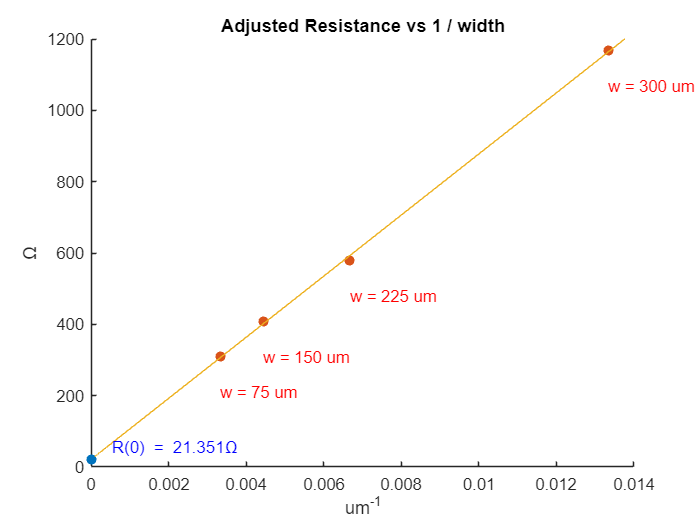


% get best fit line
Ra_coefs = polyfit(1./w, Ra, 1);

Ra_line = Ra_coefs(1) * 1./w_line + Ra_coefs(2);


% plot adjusted resistance
figure
scatter(0, Ra0, "filled", Color='red')
hold on
scatter(1./w, Ra, "filled", Color='blue')
hold on
plot_Rt = plot(1./w_line, Ra_line);
ylim([0 1200])

title("Adjusted Resistance vs 1 / width")
xlabel("um^{-1}")
ylabel("\Omega")

labelText = ["300 um" "225 um" "150 um" "75 um"];
for i = 1:4
    tX = 1 / w(i);
    tY = Ra(i) - 100;
    text(tX, tY, "w = " + labelText(i), "Color", 'red')
end
text(0.0005, 50, "R(0) = "+Ra0+"\Omega", "Color", "blue")

% compute final resistances of interest

R_contact = 0.5*Ra0 % resistance of contacts (bonds + pad)

R_contact = 10.6755

R_para1 = R_contact + rho_Al * (L1) / Ac % added on respective wire resistance

R_para1 = 10.9459

R_para2 = R_contact + rho_Al * (L2) / Ac % added on respective wire resistance

R_para2 = 11.0541

R_wire % total resistance of 5 + 7 mm of wire

R_wire = 0.6490

% erm

syms R_total R_channel R_parasitic L rho w d k

oug = R_channel == rho * L / (w * d)

$$oug = R_{\mathrm{channel}}=\frac{L\,\rho }{d\,w}$$


yipie = R_total == k * (1/w) + 2*R_parasitic

$$yipie = R_{\mathrm{total}}=2\,R_{\mathrm{parasitic}}+\frac{k}{w}$$